tbax=testballx(a6=='a');
tbay=testbally(a6=='a');
tbaz=testballz(a6=='a');

tbgx=testballx(a6=='g');
tbgy=testbally(a6=='g');
tbgz=testballz(a6=='g');

fftbax=fftshift(fft(tbax));
fftbay=fftshift(fft(tbay));
fftbaz=fftshift(fft(tbaz));

fftbgx=fftshift(fft(tbgx));
fftbgy=fftshift(fft(tbgy));
fftbgz=fftshift(fft(tbgz));

ed=[tbgx,tbgy,tbgz];
al=news(ed);

ffftbgx=fftshift(fft(al(:,1)));
ffftbgy=fftshift(fft(al(:,2)));
ffftbgz=fftshift(fft(al(:,3)));
N=length(ffftbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

santa=[tbax,tbay,tbaz];
sacria=news(santa);

ffftbax=fftshift(fft(sacria(:,1)));
ffftbay=fftshift(fft(sacria(:,2)));
ffftbaz=fftshift(fft(sacria(:,3)));
N=length(ffftbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

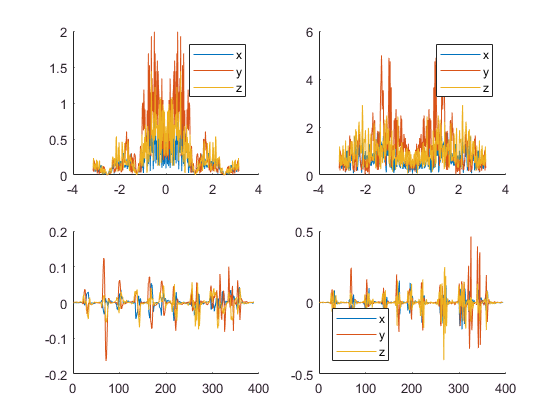

figure
subplot(2,2,1);
hold on
N=length(ffftbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffftbgx))
plot(fshifter,abs(ffftbgy))
plot(fshifter,abs(ffftbgz))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(fftbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fftbgx))
plot(fshifter,abs(fftbgy))
plot(fshifter,abs(fftbgz))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(al(:,1))
plot(al(:,2))
plot(al(:,3))
hold off

subplot(2,2,4);
hold on
plot(tbgx);
plot(tbgy);
plot(tbgz);
legend('x','y','z','Location','southwest')
hold off

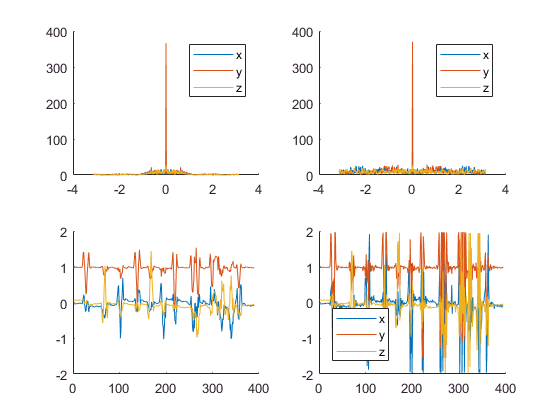

figure
subplot(2,2,1);
hold on
N=length(ffftbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffftbax))
plot(fshifter,abs(ffftbay))
plot(fshifter,abs(ffftbaz))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(fftbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fftbax))
plot(fshifter,abs(fftbay))
plot(fshifter,abs(fftbaz))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(sacria(:,1))
plot(sacria(:,2))
plot(sacria(:,3))
hold off

subplot(2,2,4);
hold on
plot(tbax);
plot(tbay);
plot(tbaz);
legend('x','y','z','Location','southwest')
hold off

dbax=dgoballx(a4=='a');
dbay=dgobally(a4=='a');
dbaz=dgoballz(a4=='a');

dbgx=dgoballx(a4=='g');
dbgy=dgobally(a4=='g');
dbgz=dgoballz(a4=='g');

ffdbax=fftshift(fft(dbax));
ffdbay=fftshift(fft(dbay));
ffdbaz=fftshift(fft(dbaz));

ffdbgx=fftshift(fft(dbgx));
ffdbgy=fftshift(fft(dbgy));
ffdbgz=fftshift(fft(dbgz));

ffdarmx=fftshift(fft(dgoarmx));
ffdarmy=fftshift(fft(dgoarmy));
ffdarmz=fftshift(fft(dgoarmz));

cura=[dbgx,dbgy,dbgz];
seiora=news(cura);

fffdbgx=fftshift(fft(seiora(:,1)));
fffdbgy=fftshift(fft(seiora(:,2)));
fffdbgz=fftshift(fft(seiora(:,3)));

seekira=[dbax,dbay,dbaz];
shakira=news(seekira);

fffdbax=fftshift(fft(shakira(:,1)));
fffdbay=fftshift(fft(shakira(:,2)));
fffdbaz=fftshift(fft(shakira(:,3)));

sicker=[dgoarmx,dgoarmy,dgoarmz];
dicker=news(sicker);
%intergrate accel for v
%the time of flight to get parabola and spin
fffdbarmx=fftshift(fft(dicker(:,1)));
fffdbarmy=fftshift(fft(dicker(:,2)));
fffdbarmz=fftshift(fft(dicker(:,3)));

figure
subplot(2,2,1);
hold on
plot(Time11,dgoarmx);
plot(Time11,dgoarmy);
plot(Time11,dgoarmz);
hold off

subplot(2,2,2);
hold on
plot(Time11(1:4315/4311:end),dicker(:,1));

plot(Time11(1:4315/4311:end),dicker(:,2));

plot(Time11(1:4315/4311:end),dicker(:,3));

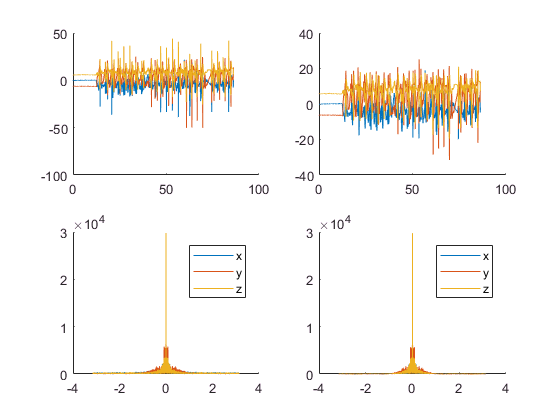

hold off

subplot(2,2,4);
hold on
N=length(fffdbarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffdbarmx))
plot(fshifter,abs(fffdbarmy))
plot(fshifter,abs(fffdbarmz))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
N=length(ffdarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffdarmx))
plot(fshifter,abs(ffdarmy))
plot(fshifter,abs(ffdarmz))
legend('x','y','z')
hold off

figure
subplot(2,2,1);
hold on
N=length(fffdbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffdbgx))
plot(fshifter,abs(fffdbgy))
plot(fshifter,abs(fffdbgz))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(ffdbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffdbgx))
plot(fshifter,abs(ffdbgy))
plot(fshifter,abs(ffdbgz))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(Time11(1:4315/778:end,:),seiora(:,1))

plot(Time11(1:4315/778:end,:),seiora(:,2))

plot(Time11(1:4315/778:end,:),seiora(:,3))

hold off

subplot(2,2,4);
hold on
plot(Time11(1:4315/782:end,:),dbgx);

plot(Time11(1:4315/782:end,:),dbgy);

plot(Time11(1:4315/782:end,:),dbgz);

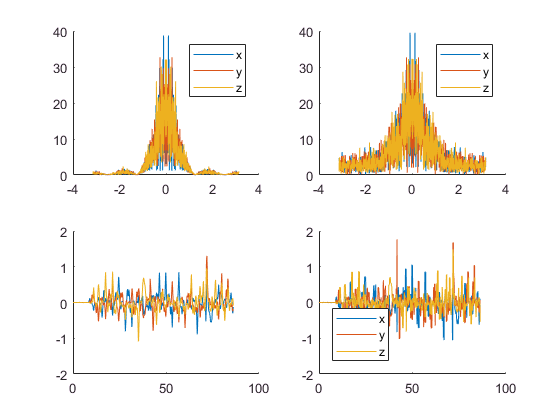

legend('x','y','z','Location','southwest')
hold off

figure
subplot(2,2,1);
hold on
N=length(fffdbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffdbax))
plot(fshifter,abs(fffdbay))
plot(fshifter,abs(fffdbaz))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(ffdbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffdbax))
plot(fshifter,abs(ffdbay))
plot(fshifter,abs(ffdbaz))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(Time11(1:4315/778:end,:),abs(shakira(:,1)))

plot(Time11(1:4315/778:end,:),abs(shakira(:,2)))

plot(Time11(1:4315/778:end,:),abs(shakira(:,3)))

hold off

subplot(2,2,4);
hold on
plot(Time11(1:4315/782:end,:),abs(dbax));

plot(Time11(1:4315/782:end,:),abs(dbay));

plot(Time11(1:4315/782:end,:),abs(dbaz));

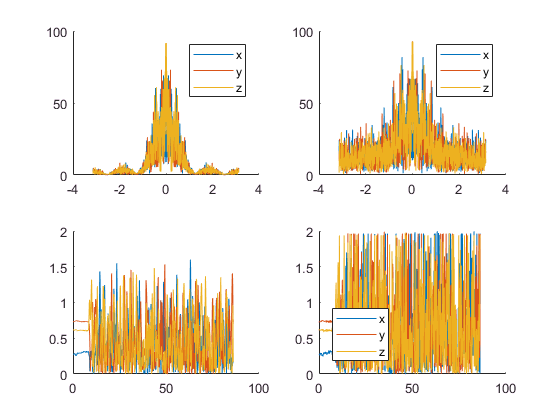

legend('x','y','z','Location','southwest')
hold off

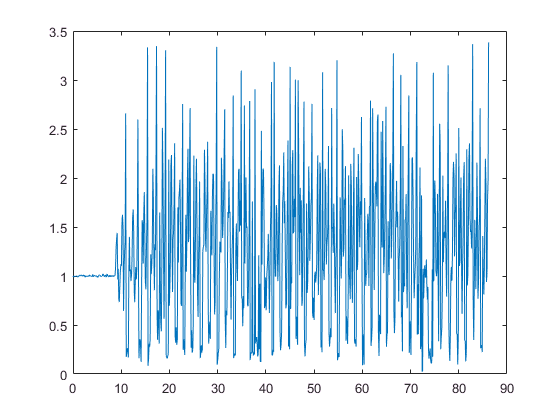

figure
plot(Time11(1:4315/782:end,:),sqrt(dbax.^2+dbay.^2+dbaz.^2))

nbax=noahballx(a2=='a');
nbay=noahbally(a2=='a');
nbaz=noahballz(a2=='a');

nbgx=noahballx(a2=='g');
nbgy=noahbally(a2=='g');
nbgz=noahballz(a2=='g');

ffbax=fftshift(fft(nbax));
ffbay=fftshift(fft(nbay));
ffbaz=fftshift(fft(nbaz));
N=length(ffbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

ffbgx=fftshift(fft(nbgx));
ffbgy=fftshift(fft(nbgy));
ffbgz=fftshift(fft(nbgz));
N=length(ffbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

ffbarmx=fftshift(fft(NoahXArm));
ffbarmy=fftshift(fft(NoahYArm));
ffbarmz=fftshift(fft(NoahZArm));
N=length(ffbarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

simon=[nbgx,nbgy,nbgz];
gurren=news(simon);

fffbgx=fftshift(fft(gurren(:,1)));
fffbgy=fftshift(fft(gurren(:,2)));
fffbgz=fftshift(fft(gurren(:,3)));
N=length(fffbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

kamina=[nbax,nbay,nbaz];
lagann=news(kamina);

fffbax=fftshift(fft(lagann(:,1)));
fffbay=fftshift(fft(lagann(:,2)));
fffbaz=fftshift(fft(lagann(:,3)));
N=length(fffbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

sadder=[NoahXArm,NoahYArm,NoahZArm];
madder=news(sadder);
%intergrate accel for v
%the time of flight to get parabola and spin
fffbarmx=fftshift(fft(madder(:,1)));
fffbarmy=fftshift(fft(madder(:,2)));
fffbarmz=fftshift(fft(madder(:,3)));
N=length(fffbarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

figure
subplot(2,1,1);
hold on
plot(Time1,NoahXArm);
plot(Time1,NoahYArm);
plot(Time1,NoahZArm);
legend('x','y','z')
title('Accelration Over Time (unfiltered)')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
hold off

subplot(2,1,2);
hold on
plot(Time1(1:596/592:end),madder(:,1));

plot(Time1(1:596/592:end),madder(:,2));

plot(Time1(1:596/592:end),madder(:,3));

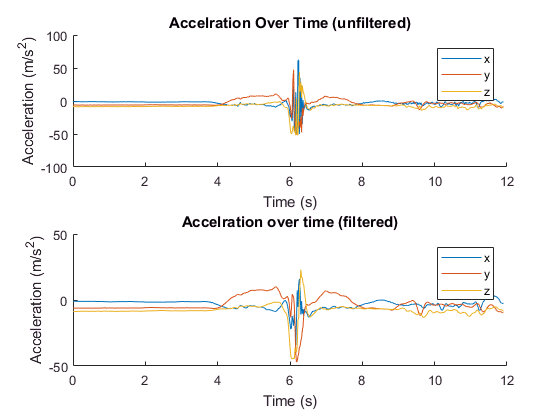

legend('x','y','z')
title('Accelration over time (filtered)')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
hold off

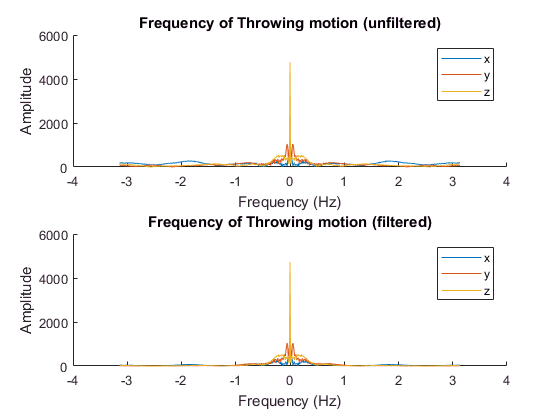


figure
subplot(2,1,2);
hold on
N=length(fffbarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffbarmx))
plot(fshifter,abs(fffbarmy))
plot(fshifter,abs(fffbarmz))
legend('x','y','z')
title('Frequency of Throwing motion (filtered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

subplot(2,1,1);
hold on
N=length(ffbarmx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffbarmx))
plot(fshifter,abs(ffbarmy))
plot(fshifter,abs(ffbarmz))
legend('x','y','z')
title('Frequency of Throwing motion (unfiltered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

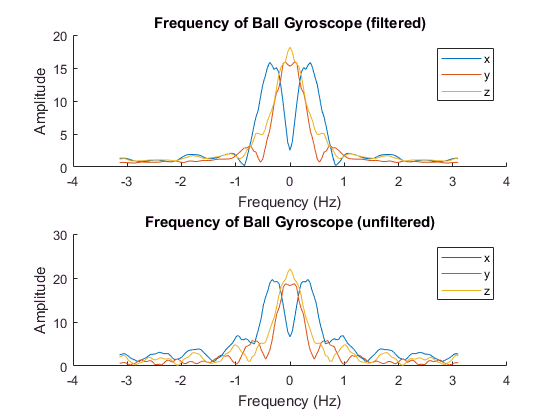

figure
subplot(2,1,1);
hold on
N=length(fffbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffbgx))
plot(fshifter,abs(fffbgy))
plot(fshifter,abs(fffbgz))
legend('x','y','z')
title('Frequency of Ball Gyroscope (filtered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

subplot(2,1,2);
hold on
N=length(ffbgx);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffbgx))
plot(fshifter,abs(ffbgy))
plot(fshifter,abs(ffbgz))
legend('x','y','z')
title('Frequency of Ball Gyroscope (unfiltered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off


figure
subplot(2,1,1);
hold on
plot(Time1(1:596/150:end,:),gurren(:,1))

plot(Time1(1:596/150:end,:),gurren(:,2))

plot(Time1(1:596/150:end,:),gurren(:,3))

legend('x','y','z','Location','southwest')
title('Angular Velocity Over Time (filtered)')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off

subplot(2,1,2);
hold on
plot(Time1(1:596/154:end,:),nbgx);

plot(Time1(1:596/154:end,:),nbgy);

plot(Time1(1:596/154:end,:),nbgz);

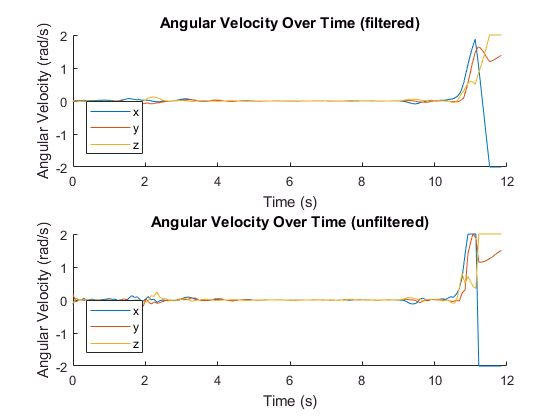

legend('x','y','z','Location','southwest')
title('Angular Velocity Over Time (unfiltered)')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off

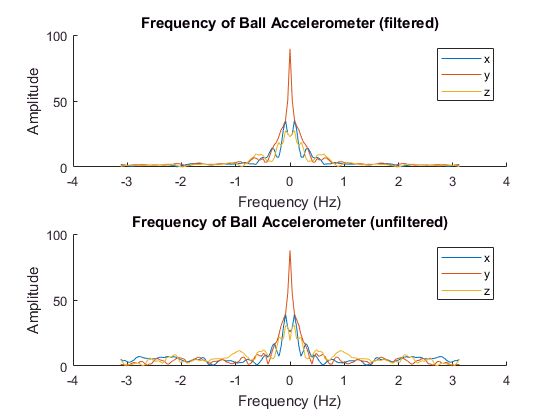

figure
subplot(2,1,1);
hold on
N=length(fffbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffbax))
plot(fshifter,abs(fffbay))
plot(fshifter,abs(fffbaz))
legend('x','y','z')
title('Frequency of Ball Accelerometer (filtered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

subplot(2,1,2);
hold on
N=length(ffbax);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffbax))
plot(fshifter,abs(ffbay))
plot(fshifter,abs(ffbaz))
legend('x','y','z')
title('Frequency of Ball Accelerometer (unfiltered)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off


figure
subplot(2,1,1);
hold on
plot(Time1(1:596/151:end,:),lagann(:,1))

plot(Time1(1:596/151:end,:),lagann(:,2))

plot(Time1(1:596/151:end,:),lagann(:,3))

legend('x','y','z','Location','north')
title('Acceleration Over Time (filtered)')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
hold off

subplot(2,1,2);
hold on
plot(Time1(1:596/155:end,:),nbax);

plot(Time1(1:596/155:end,:),nbay);

plot(Time1(1:596/155:end,:),nbaz);

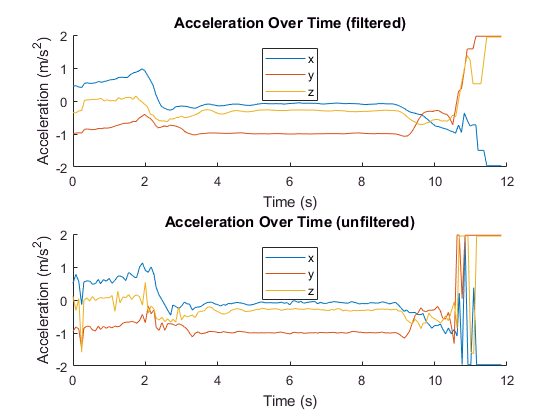

legend('x','y','z','Location','north')
title('Acceleration Over Time (unfiltered)')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
hold off

Time1(find(Time==5):find(Time==8),:)

ans =     5.0200
    5.0400
    5.0600
    5.0800
    5.1000
    5.1200
    5.1400
    5.1600
    5.1800
    5.2000


NoahXArm(find(Time1==5):find(Time1==8),:)

ans =    -4.3400
   -3.3800
   -5.1500
   -5.2600
   -5.5400
   -5.5400
   -5.3200
   -5.2000
   -5.4600
   -5.6000


armvelocx=eate(Time1(find(Time==5):find(Time==8),:),NoahXArm(find(Time1==5):find(Time1==8),:));
armvelocy=eate(Time1(find(Time==5):find(Time==8),:),NoahYArm(find(Time1==5):find(Time1==8),:));
armvelocz=eate(Time1(find(Time==5):find(Time==8),:),NoahZArm(find(Time1==5):find(Time1==8),:));

armposx=ompe(Time1(find(Time1==5):find(Time1==8),:),armvelocx,NoahXArm(find(Time1==5):find(Time1==8),:));
armposy=ompe(Time1(find(Time1==5):find(Time1==8),:),armvelocy,NoahYArm(find(Time1==5):find(Time1==8),:));
armposz=ompe(Time1(find(Time1==5):find(Time1==8),:),armvelocz,NoahZArm(find(Time1==5):find(Time1==8),:));

tim=Time(1:596/155:end)

tim =        NaN
    0.0600
    0.1400
    0.2200
    0.2800
    0.3600
    0.4400
    0.5200
    0.6000
    0.6800


timee=tim(find(tim==6):find(tim==8.02),:)


timee =

  0×1 empty double column vector



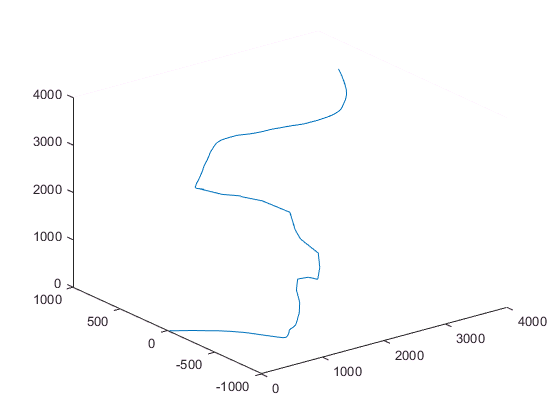


ballvelocx=eat(tim(find(tim==6):find(tim==8.02),:),nbax2(find(tim==6):find(tim==8.02),:));
ballvelocy=eat(tim(find(tim==6):find(tim==8.02),:),nbay2(find(tim==6):find(tim==8.02),:));
ballvelocz=eat(tim(find(tim==6):find(tim==8.02),:),nbaz2(find(tim==6):find(tim==8.02),:));

ballposx=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocx,nbax2(find(tim==6):find(tim==8.02),:));
ballposy=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocy,nbay2(find(tim==6):find(tim==8.02),:));
ballposz=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocz,nbaz2(find(tim==6):find(tim==8.02),:));

figure
plot3(-ballposx,-ballposy,-ballposz)

figure
plot3(-armposx,-armposy,-armposz) 

nbax2=noahballx2(a2=='a');
nbay2=noahbally2(a2=='a');
nbaz2=noahballz2(a2=='a');

nbgx2=noahballx2(a2=='g');
nbgy2=noahbally2(a2=='g');
nbgz2=noahballz2(a2=='g');

ffbax2=fftshift(fft(nbax2));
ffbay2=fftshift(fft(nbay2));
ffbaz2=fftshift(fft(nbaz2));
N=length(ffbax2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

%fft of accel noah 2
akko=[nbax2,nbay2,nbaz2];
flcl=news(akko);

fffbax2=fftshift(fft(flcl(:,1)));
fffbay2=fftshift(fft(flcl(:,2)));
fffbaz2=fftshift(fft(flcl(:,3)));
N=length(fffbax2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

%

ffbgx2=fftshift(fft(nbgx2));
ffbgy2=fftshift(fft(nbgy2));
ffbgz2=fftshift(fft(nbgz2));
N=length(ffbgx2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

diana=[nbgx2,nbgy2,nbgz2];
progressive=news(diana);

fffbgx2=fftshift(fft(progressive(:,1)));
fffbgy2=fftshift(fft(progressive(:,2)));
fffbgz2=fftshift(fft(progressive(:,3)));
N=length(fffbgx2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

figure
subplot(2,2,1);
hold on
N=length(fffbax2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffbax2))
plot(fshifter,abs(fffbay2))
plot(fshifter,abs(fffbaz2))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(ffbax2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffbax2))
plot(fshifter,abs(ffbay2))
plot(fshifter,abs(ffbaz2))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(Time(1:458/151:end,:),flcl(:,1))

plot(Time(1:458/151:end,:),flcl(:,2))

plot(Time(1:458/151:end,:),flcl(:,3))

hold off

subplot(2,2,4);
hold on
plot(Time(1:458/155:end,:),nbax2);

plot(Time(1:458/155:end,:),nbay2);

plot(Time(1:458/155:end,:),nbaz2);

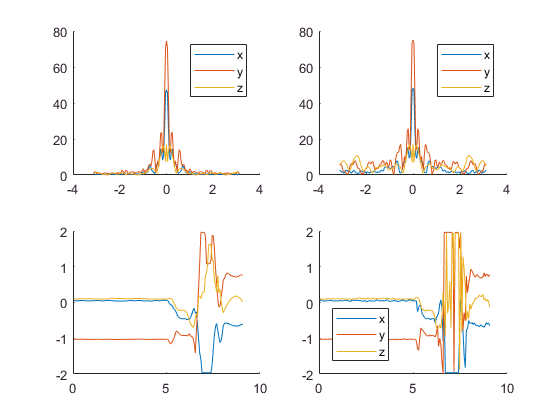

legend('x','y','z','Location','southwest')
hold off

figure
subplot(2,2,1);
hold on
N=length(fffbgx2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(fffbgx2))
plot(fshifter,abs(fffbgy2))
plot(fshifter,abs(fffbgz2))
legend('x','y','z')
hold off

subplot(2,2,2);
hold on
N=length(ffbgx2);
fshifter = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
plot(fshifter,abs(ffbgx2))
plot(fshifter,abs(ffbgy2))
plot(fshifter,abs(ffbgz2))
legend('x','y','z')
hold off

subplot(2,2,3);
hold on
plot(Time(1:458/150:end,:),progressive(:,1))

plot(Time(1:458/150:end,:),progressive(:,2))

plot(Time(1:458/150:end,:),progressive(:,3))

hold off

subplot(2,2,4);
hold on
plot(Time(1:458/154:end,:),nbgx2);

plot(Time(1:458/154:end,:),nbgy2);

plot(Time(1:458/154:end,:),nbgz2);

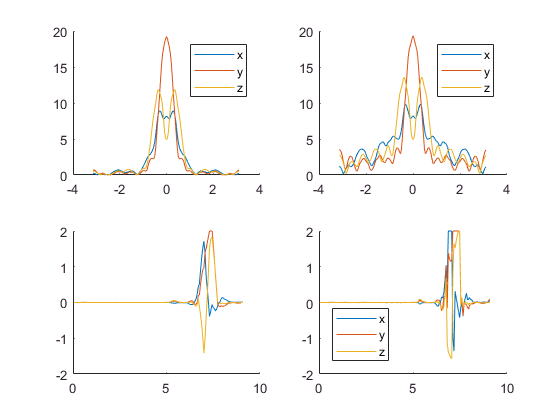

legend('x','y','z','Location','southwest')
hold off

armvelocx2=eat(Time(find(Time==4):find(Time==6),:),NoahXArm2(find(Time==4):find(Time==6),:));
armvelocy2=eat(Time(find(Time==4):find(Time==6),:),NoahYArm2(find(Time==4):find(Time==6),:));
armvelocz2=eat(Time(find(Time==4):find(Time==6),:),NoahZArm2(find(Time==4):find(Time==6),:));

armposx2=omp(Time(find(Time==4):find(Time==6),:),armvelocx2,NoahXArm2(find(Time==4):find(Time==6),:));
armposy2=omp(Time(find(Time==4):find(Time==6),:),armvelocy2,NoahYArm2(find(Time==4):find(Time==6),:));
armposz2=omp(Time(find(Time==4):find(Time==6),:),armvelocz2,NoahZArm2(find(Time==4):find(Time==6),:));

tim=Time(1:458/155:end)

tim =        NaN
    0.0400
    0.1000
    0.1600
    0.2200
    0.2800
    0.3400
    0.4000
    0.4600
    0.5200


timee=tim(find(tim==6):find(tim==8.02),:)

timee =     6.0000
    6.0600
    6.1200
    6.1800
    6.2400
    6.3000
    6.3600
    6.4200
    6.4800
    6.5400


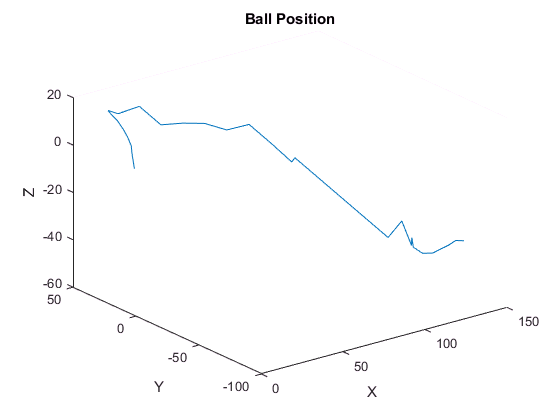


ballvelocx2=eat(tim(find(tim==6):find(tim==8.02),:),nbax2(find(tim==6):find(tim==8.02),:));
ballvelocy2=eat(tim(find(tim==6):find(tim==8.02),:),nbay2(find(tim==6):find(tim==8.02),:));
ballvelocz2=eat(tim(find(tim==6):find(tim==8.02),:),nbaz2(find(tim==6):find(tim==8.02),:));

ballposx2=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocx2,nbax2(find(tim==6):find(tim==8.02),:));
ballposy2=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocy2,nbay2(find(tim==6):find(tim==8.02),:));
ballposz2=omp(tim(find(tim==6):find(tim==8.02),:),ballvelocz2,nbaz2(find(tim==6):find(tim==8.02),:));

figure
plot3(-ballposx2,-ballposy2,-ballposz2)
title('Ball Position')
xlabel('X')
ylabel('Y')
zlabel('Z')

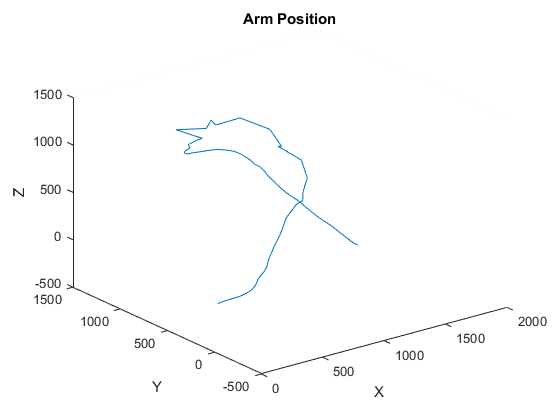


figure
plot3(-armposx2,-armposy2,-armposz2) 
title('Arm Position')
xlabel('X')
ylabel('Y')
zlabel('Z')

tim=Time(1:458/154:end);

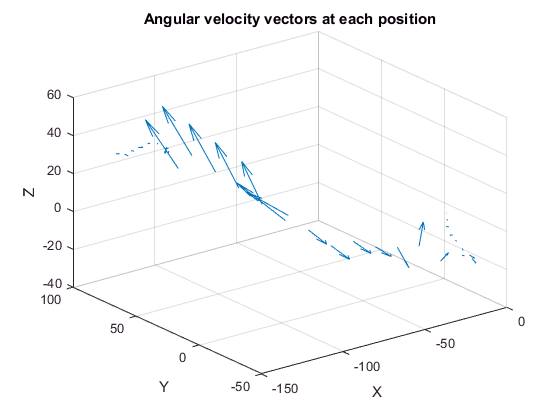

figure
quiver3(ballposx2,ballposy2,ballposz2,nbgx2(find(tim==6.1):find(tim==8),:),nbgy2(find(tim==6.1):find(tim==8),:),nbgz2(find(tim==6.1):find(tim==8),:))
title('Angular velocity vectors at each position')
xlabel('X')
ylabel('Y')
zlabel('Z')

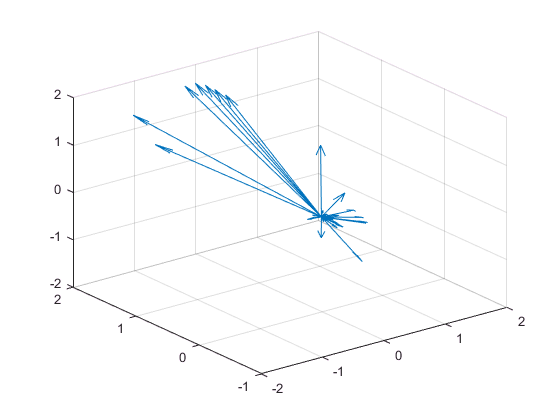


figure
quiver3(zeros(size(nbgx2(find(tim==6.1):find(tim==8),:))),zeros(size(nbgx2(find(tim==6.1):find(tim==8),:))),zeros(size(nbgx2(find(tim==6.1):find(tim==8),:))),nbgx2(find(tim==6.1):find(tim==8),:),nbgy2(find(tim==6.1):find(tim==8),:),nbgz2(find(tim==6.1):find(tim==8),:))

function ff= news(x)
    s=size(x);
    ff=zeros(0,0);
    for r=1:s(2)
        y=[];
        for n=3:s(1)-2
            y=[y;(x(n,r)+x(n+1,r)+x(n-1,r)+x(n+2,r)+x(n-2,r))/5];
        end
        ff=[ff,y];
    end
end

function vs = eat(t,a)
    v= 0;
    vs=[];
    for r = 3:length(t)
        v=a(r,:)*(t(r,:)-t(r-1,:));
        vs=[vs;v];
    end
end

function ps = omp(t,v,a)
    p= 0;
   ps=[];
    for r = 3:length(t)
        p=p+v(r-2,:)*t(r,:)+0.5*(a(r,:)*t(r,:));
        ps=[ps;p];
    end
end

function vs = eate(t,a)
    v= 0;
    vs=[];
    for r = 2:length(t)
        v=a(r,:)*(t(r,:)-t(r-1,:));
        vs=[vs;v];
    end
end

function ps = ompe(t,v,a)
    p= 0;
   ps=[];
    for r = 2:length(t)
        p=p+v(r-1,:)*t(r,:)+0.5*(a(r,:)*t(r,:));
        ps=[ps;p];
    end
end

